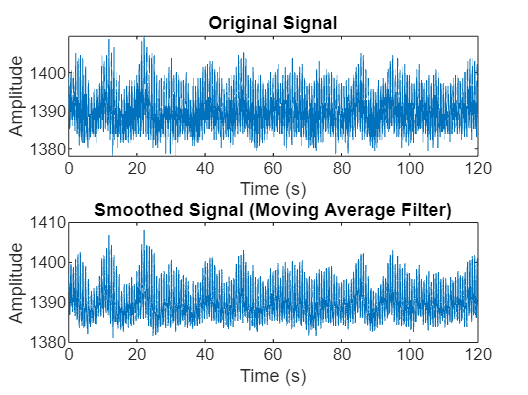

% Load the signal
load('PPG_CLAWDAS_ELD_read_subset_noise.mat');

% Extracting the first signal
signal = CLAWDAS_OLD_read_subset_noise(1).TEXT;

% Defining sampling frequency
Fs = 128;

% Applying  Moving Average Filter
windowSize = 6;
smoothed_signal = movmean(signal, windowSize);

% Ploting the original and filtered signal
t = (0:length(signal)-1) / Fs;
figure;
subplot(2,1,1);
plot(t, signal);
title('Original Signal');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(2,1,2);
plot(t, smoothed_signal);
title('Smoothed Signal (Moving Average Filter)');
xlabel('Time (s)');
ylabel('Amplitude');

disp("finish")

finish


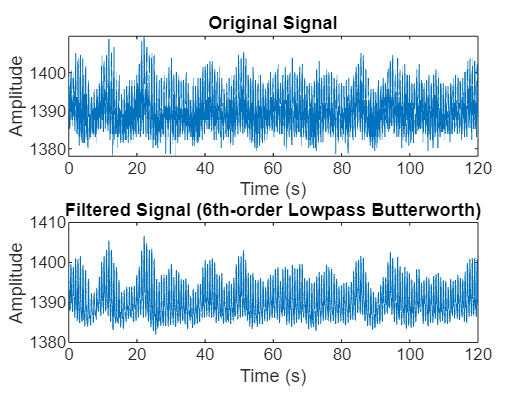

% Define filter parameters
n = 6;                  % Filter order
cutoff_freq = 4;        % Cutoff frequency in Hz

% Design the filter
[b, a] = butter(n, cutoff_freq/(Fs/2), 'low');

% Apply the filter
filtered_signal = filtfilt(b, a, signal);

% Plot the original and filtered signal
figure;
subplot(2,1,1);
plot(t, signal);
title('Original Signal');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(2,1,2);
plot(t, filtered_signal);
title('Filtered Signal (6th-order Lowpass Butterworth)');
xlabel('Time (s)');
ylabel('Amplitude');

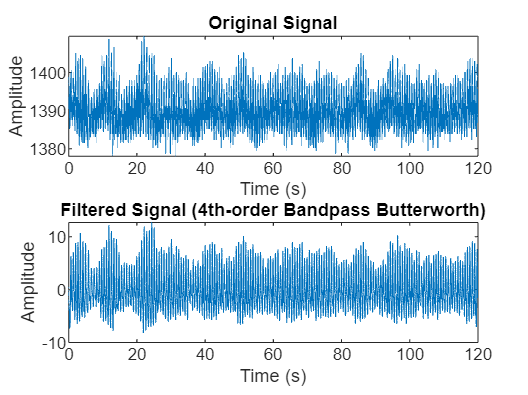

% Define filter parameters
low_cutoff = 0.4;       % Lower cutoff frequency in Hz
high_cutoff = 4;        % Upper cutoff frequency in Hz

% Design the filter
[b, a] = butter(4, [low_cutoff high_cutoff]/(Fs/2), 'bandpass');

% Apply the filter
filtered_signal = filtfilt(b, a, signal);

% Plot the original and filtered signal
figure;
subplot(2,1,1);
plot(t, signal);
title('Original Signal');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(2,1,2);
plot(t, filtered_signal);
title('Filtered Signal (4th-order Bandpass Butterworth)');
xlabel('Time (s)');
ylabel('Amplitude');

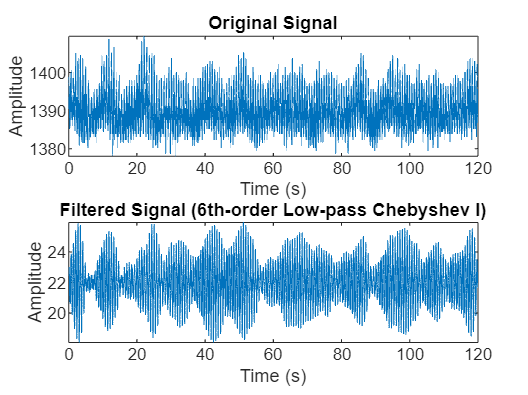

% Define filter parameters
ripple = 18;            % Passband ripple in dB
cutoff_freq = 6;        % Cutoff frequency in Hz

% Design the filter
[b, a] = cheby1(6, ripple, cutoff_freq/(Fs/2), 'low');

% Apply the filter
filtered_signal = filtfilt(b, a, signal);

% Plot the original and filtered signal
figure;
subplot(2,1,1);
plot(t, signal);
title('Original Signal');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(2,1,2);
plot(t, filtered_signal);
title('Filtered Signal (6th-order Low-pass Chebyshev I)');
xlabel('Time (s)');
ylabel('Amplitude');

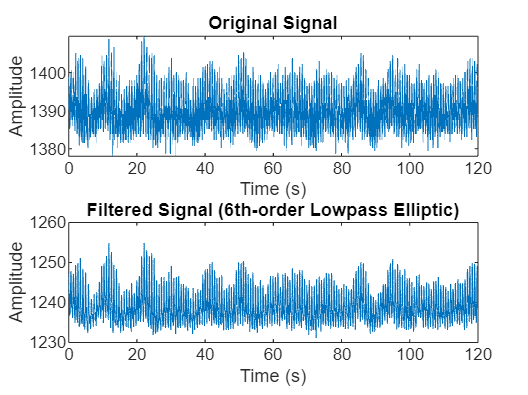

% Define filter parameters
ripple = 0.5;           % Passband ripple in dB
attenuation = 20;       % Stopband attenuation in dB
cutoff_freq = 6;        % Cutoff frequency in Hz

% Design the filter
[b, a] = ellip(6, ripple, attenuation, cutoff_freq/(Fs/2), 'low');

% Apply the filter
filtered_signal = filtfilt(b, a, signal);

% Plot the original and filtered signal
figure;
subplot(2,1,1);
plot(t, signal);
title('Original Signal');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(2,1,2);
plot(t, filtered_signal);
title('Filtered Signal (6th-order Lowpass Elliptic)');
xlabel('Time (s)');
ylabel('Amplitude');

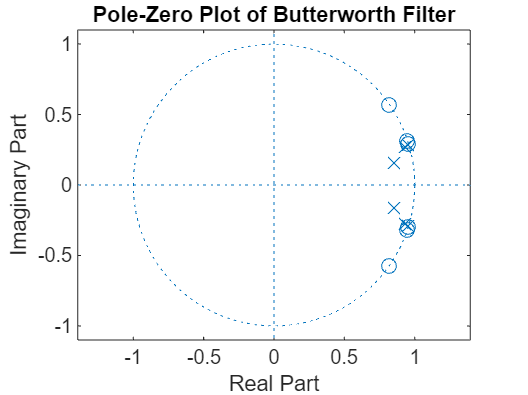

% For Butterworth filter as an example
figure;
zplane(b, a);
title('Pole-Zero Plot of Butterworth Filter');

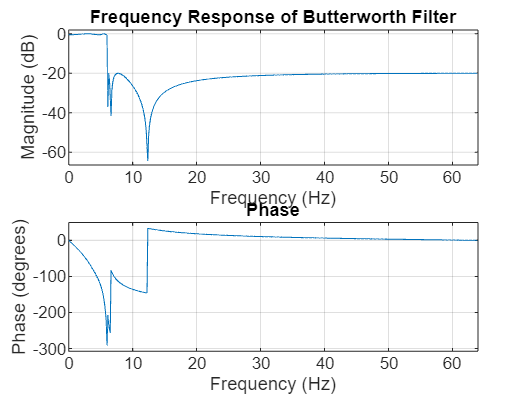

% For Butterworth filter as an example
figure;
freqz(b, a, [], Fs);
title('Frequency Response of Butterworth Filter');

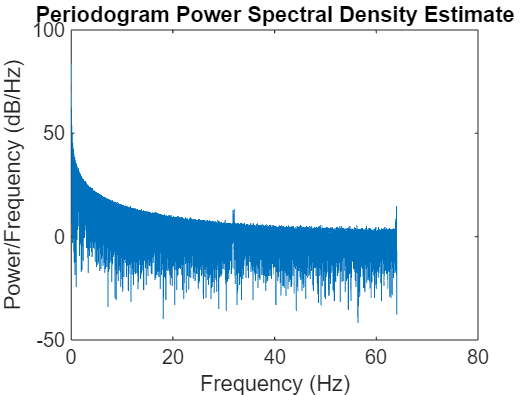

% Compute the periodogram
[pxx, f] = periodogram(signal, [], [], Fs);

% Plot the periodogram
figure;
plot(f, 10*log10(pxx));
title('Periodogram Power Spectral Density Estimate');
xlabel('Frequency (Hz)');
ylabel('Power/Frequency (dB/Hz)');

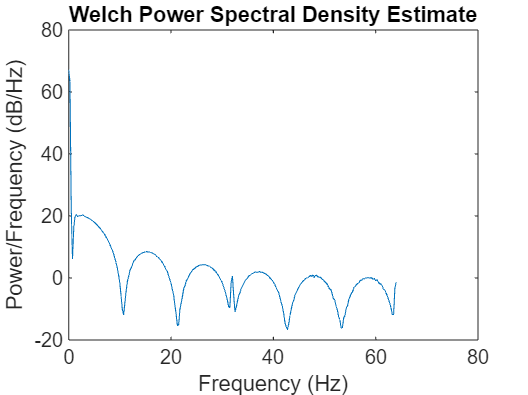

% Define parameters
windowSize = 500;
noverlap = 300;

% Estimate the PSD using Welch's method
[pxx, f] = pwelch(signal, windowSize, noverlap, [], Fs);

% Plot the PSD
figure;
plot(f, 10*log10(pxx));
title('Welch Power Spectral Density Estimate');
xlabel('Frequency (Hz)');
ylabel('Power/Frequency (dB/Hz)');

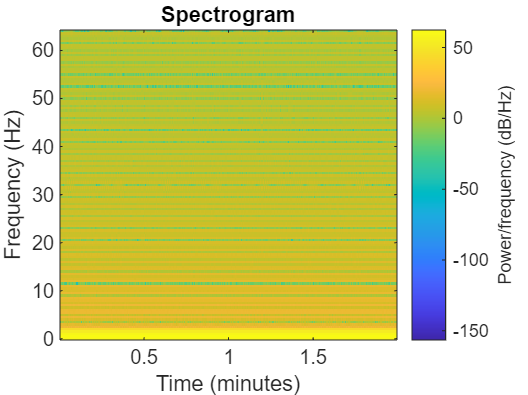

% Generate and visualize the spectrogram
windowSize = 100;
noverlap = windowSize / 2;
figure;
spectrogram(signal, windowSize, noverlap, [], Fs, 'yaxis');
title('Spectrogram');

Exercise 2: L'ets Compute the Power Spectral Density

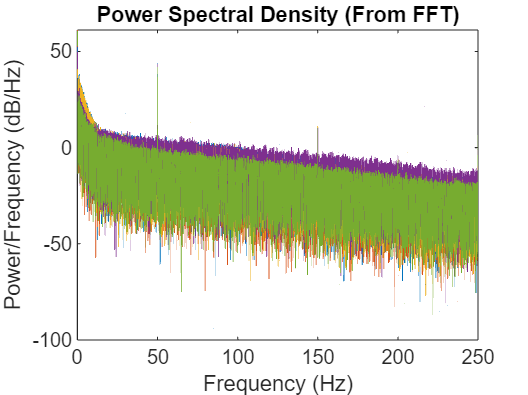

load('EEG_TCDM.mat');
signal = EEGDATA';

%% 2. Compute the Power Spectral Density of the signal starting from its Fourier transform and compare 
% the result obtained with the ones obtained using the function "periodogram”
Fs = 500;

% PSD using the Fourier transform
N = length(signal);
signal_dft = fft(signal); % Discete Fourier Transform
signal_dft = signal_dft(1:N/2+1,1:5); % To remove the duplicate coefficients
psd_signal = (1/(Fs*N)) * abs(signal_dft).^2; % Power Spectral Density
psd_signal(2:end-1) = 2*psd_signal(2:end-1); % Zero frequency (DC) and the Nyquist frequency do not occur twice
freq = 0:Fs/N:Fs/2;

figure;
plot(freq, 10*log10(psd_signal));
title('Power Spectral Density (From FFT)');
xlabel('Frequency (Hz)');
ylabel('Power/Frequency (dB/Hz)');

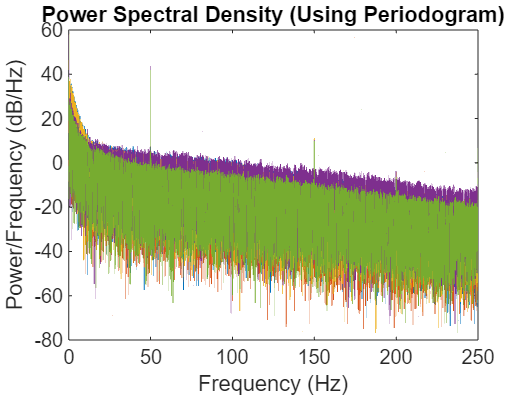


[pxx, f] = periodogram(signal, [], [], Fs);

figure;
plot(f, 10*log10(pxx));
title('Power Spectral Density (Using Periodogram)');
xlabel('Frequency (Hz)');
ylabel('Power/Frequency (dB/Hz)');

disp("finished suucecsuful")

finished suucecsuful


Exercise 3: L'ets Remove the power-line noise from the EEG signals using a Second-Order IIR notch filter

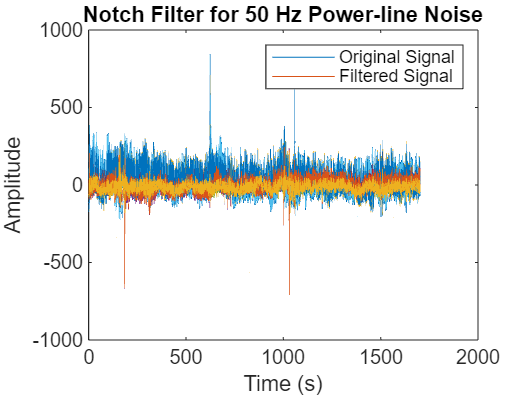

Fs = 500; % Assuming the sampling frequency is 500 Hz
wo = 50 / (Fs / 2); % 50 Hz frequency to be removed
bw = wo / 35; % Bandwidth
[b, a] = iirnotch(wo, bw);
filtered_signal_notch = filtfilt(b, a, signal);
t = (0:length(signal)-1) / Fs;
figure;
plot(t, signal);
hold on;
plot(t, filtered_signal_notch);
title('Notch Filter for 50 Hz Power-line Noise');
legend('Original Signal', 'Filtered Signal');
xlabel('Time (s)');
ylabel('Amplitude');

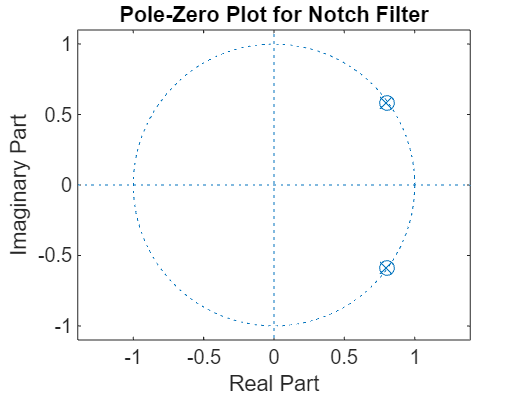


figure;
zplane(b, a);
title('Pole-Zero Plot for Notch Filter');

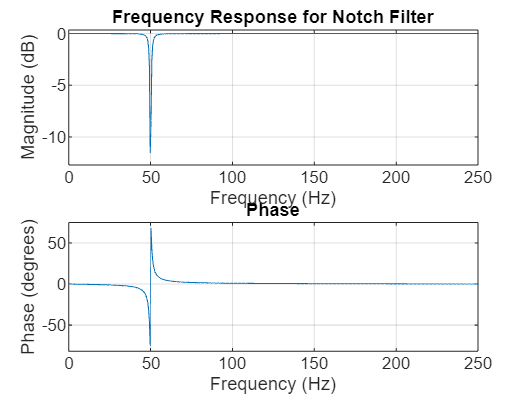


figure;
freqz(b, a, [], Fs);
title('Frequency Response for Notch Filter');

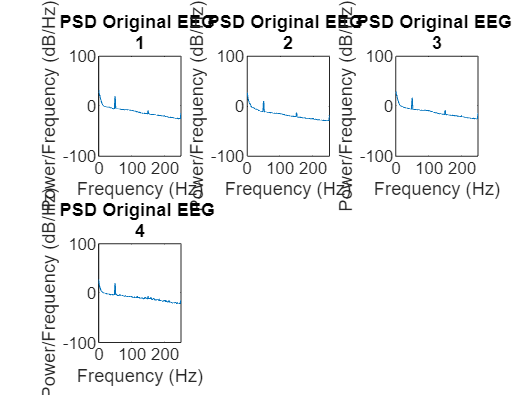

% 1. Load the signals
% Load EEG data (sample rate = 500Hz) and single channel data (sample rate = 128Hz)

load('EEG_TCDM.mat'); % Load EEG data
EEG_signals = EEGDATA'; % Transpose EEG data for processing
Fs_EEG = 500; % Sampling frequency of EEG data

load('single_ch.mat'); % Load single channel data
single_channel = single_ch'; % Transpose single channel data for processing
Fs_single = 128; % Sampling frequency of single channel data

% 2. Remove the power-line noise from the signals using a Second-Order IIR notch filter

% Define parameters for notch filter to remove 50 Hz noise from EEG signals
power_line_noise_EEG = 50; % Power-line noise frequency for EEG data (Hz)
normalized_frequency_EEG = power_line_noise_EEG / (Fs_EEG / 2); % Normalized frequency for notch filter
bandwidth_EEG = normalized_frequency_EEG / 35; % Bandwidth for notch filter (Quality Factor = 35)

% Design notch filter and apply to EEG signals
[filter_b_EEG, filter_a_EEG] = iirnotch(normalized_frequency_EEG, bandwidth_EEG); % Filter coefficients
filtered_EEG = filtfilt(filter_b_EEG, filter_a_EEG, EEG_signals); % Apply notch filter

% Define parameters for notch filter to remove 60 Hz noise from single channel data
power_line_noise_single = 60; % Power-line noise frequency for single channel data (Hz)
normalized_frequency_single = power_line_noise_single / (Fs_single / 2); % Normalized frequency for notch filter
bandwidth_single = normalized_frequency_single / 35; % Bandwidth for notch filter (Quality Factor = 35)

% Design notch filter and apply to single channel data
[filter_b_single, filter_a_single] = iirnotch(normalized_frequency_single, bandwidth_single); % Filter coefficients
filtered_single = filtfilt(filter_b_single, filter_a_single, single_channel); % Apply notch filter

% 3. Calculate and plot Power Spectral Density (PSD) using Welch's method

% Calculate PSD of original and filtered EEG signals
[psd_EEG_original, freq_EEG_original] = pwelch(EEG_signals, 500, 300, [], Fs_EEG);
[psd_EEG_filtered, freq_EEG_filtered] = pwelch(filtered_EEG, 500, 300, [], Fs_EEG);

% Calculate PSD of original and filtered single channel signals
[psd_single_original, freq_single_original] = pwelch(single_channel, 300, 100, [], Fs_single);
[psd_single_filtered, freq_single_filtered] = pwelch(filtered_single, 300, 100, [], Fs_single);

% Plot PSD of original EEG signals
figure(1)
for i = 1:4
    subplot(2, 3, i)
    plot(freq_EEG_original, 10*log10(psd_EEG_original(:,i)));
    title(["PSD Original EEG ", num2str(i)])
    xlabel("Frequency (Hz)")
    ylabel("Power/Frequency (dB/Hz)")
    ylim([-100, 100])
end

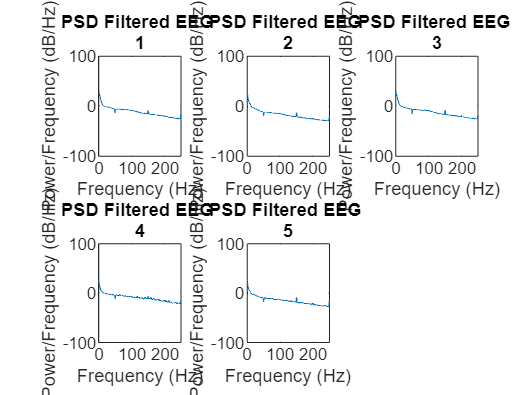


% Plot PSD of filtered EEG signals
figure(2)
for i = 1:5
    subplot(2, 3, i)
    plot(freq_EEG_filtered, 10*log10(psd_EEG_filtered(:,i)));
    title(["PSD Filtered EEG ", num2str(i)])
    xlabel("Frequency (Hz)")
    ylabel("Power/Frequency (dB/Hz)")
    ylim([-100, 100])
end

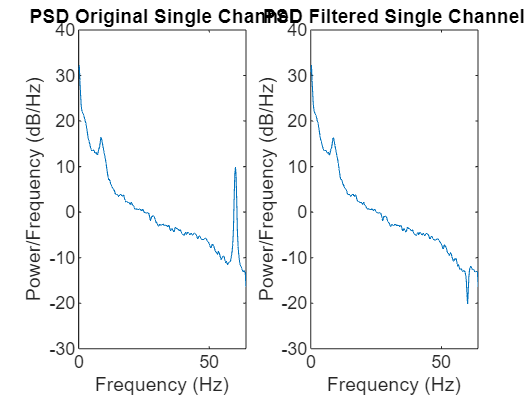


% Plot PSD of original and filtered single channel signals
figure(3)
subplot(1, 2, 1)
plot(freq_single_original, 10*log10(psd_single_original));
title("PSD Original Single Channel")
xlabel("Frequency (Hz)")
ylabel("Power/Frequency (dB/Hz)")
ylim([-30, 40])
xlim([0, max(freq_single_filtered)])

subplot(1, 2, 2)
plot(freq_single_filtered, 10*log10(psd_single_filtered));
title("PSD Filtered Single Channel")
xlabel("Frequency (Hz)")
ylabel("Power/Frequency (dB/Hz)")
ylim([-30, 40])
xlim([0, max(freq_single_filtered)])

Exercise 4: Generate Spectrogram and Periodogram

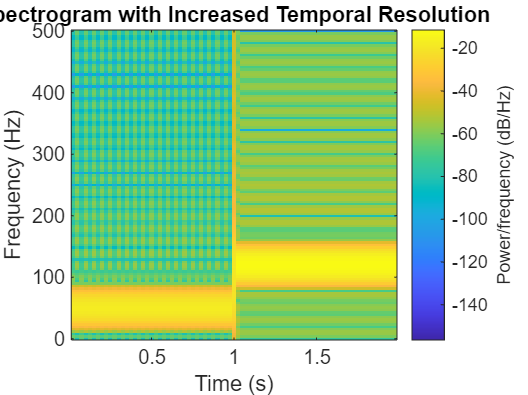

Fs = 1000;
t1 = (0:1/Fs:1)';
t2 = (1:1/Fs:2)';
t = [t1; t2];
y = [sin(2*pi*50*t1); 2*sin(2*pi*120*t2)];

windowSize = 50; % Increase temporal resolution
Noverlap = windowSize / 2; 

figure;
spectrogram(y, windowSize, Noverlap, [], Fs, 'yaxis');
title('Spectrogram with Increased Temporal Resolution');

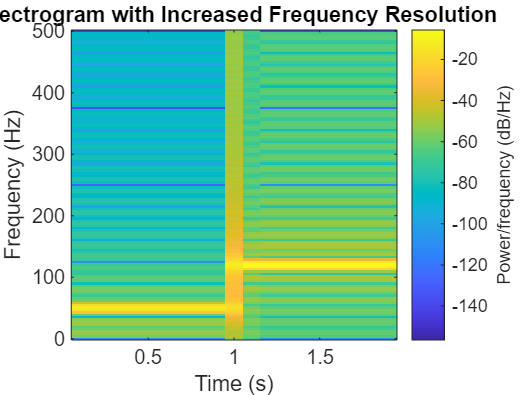

windowSize = 200; % Increase frequency resolution
Noverlap = floor(windowSize / 2);

figure;
spectrogram(y, windowSize, Noverlap, [], Fs, 'yaxis');
title('Spectrogram with Increased Frequency Resolution');

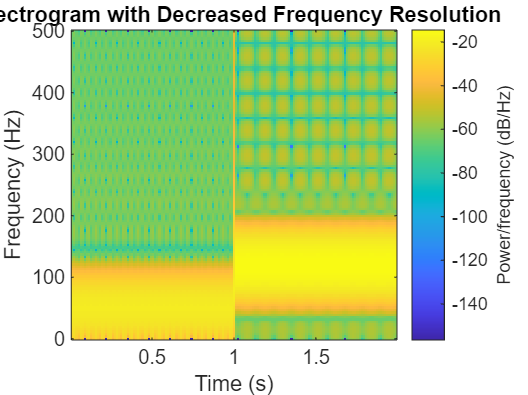

windowSize = 25; % Decrease frequency resolution
Noverlap = floor(windowSize / 2);

figure;
spectrogram(y, windowSize, Noverlap, [], Fs, 'yaxis');
title('Spectrogram with Decreased Frequency Resolution');

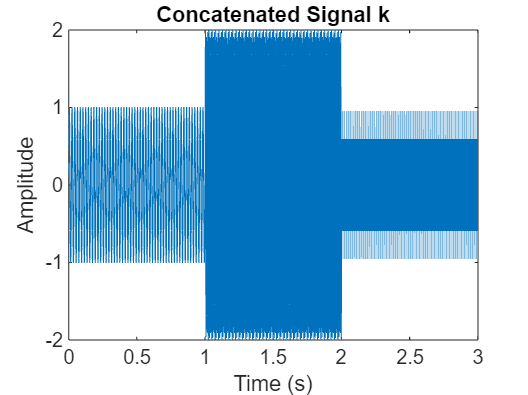

k = [y; sin(2*pi*400*(0:1/Fs:1)')];
figure;
plot((0:length(k)-1)/Fs, k);
title('Concatenated Signal k');
xlabel('Time (s)');
ylabel('Amplitude');

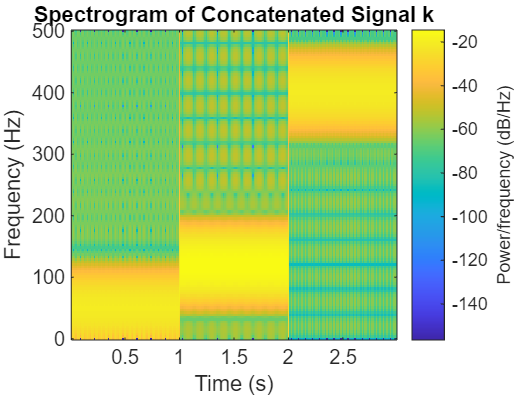


figure;
spectrogram(k, windowSize, Noverlap, [], Fs, 'yaxis');
title('Spectrogram of Concatenated Signal k');

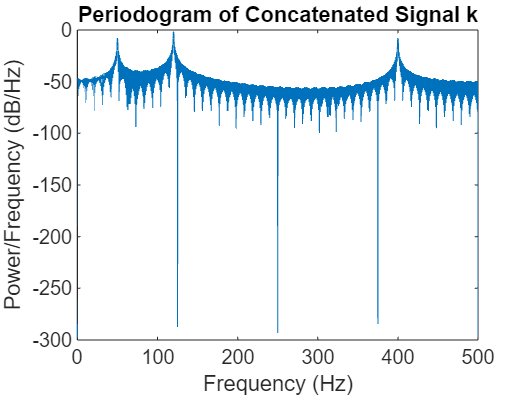


[pxx, f] = periodogram(k, [], [], Fs);
figure;
plot(f, 10*log10(pxx));
title('Periodogram of Concatenated Signal k');
xlabel('Frequency (Hz)');
ylabel('Power/Frequency (dB/Hz)');

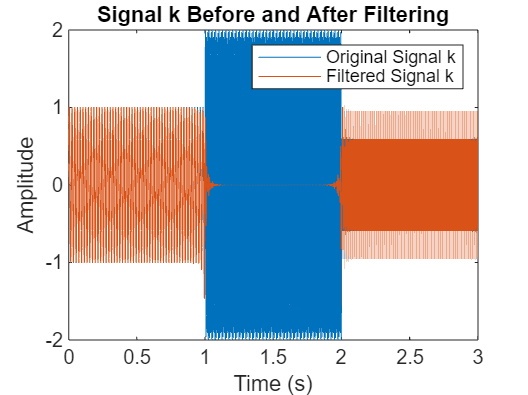

[b, a] = butter(4, [100 140] / (Fs / 2), 'stop');
filtered_k = filtfilt(b, a, k);

figure;
plot((0:length(k)-1)/Fs, k);
hold on;
plot((0:length(k)-1)/Fs, filtered_k);
title('Signal k Before and After Filtering');
legend('Original Signal k', 'Filtered Signal k');
xlabel('Time (s)');
ylabel('Amplitude');

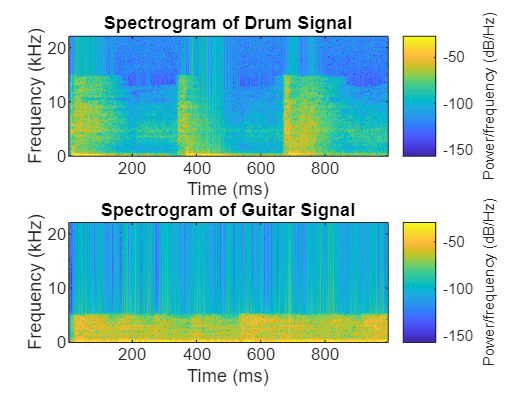

[drum, Fs_drum] = audioread('drum.wav');
[guitar, Fs_guitar] = audioread('guitar.wav');

windowSize = 256;
Noverlap = windowSize / 2;

figure;
subplot(2,1,1);
spectrogram(drum, windowSize, Noverlap, [], Fs_drum, 'yaxis');
title('Spectrogram of Drum Signal');

subplot(2,1,2);
spectrogram(guitar, windowSize, Noverlap, [], Fs_guitar, 'yaxis');
title('Spectrogram of Guitar Signal');